clearvars
addpath("layer configs");

**Setting the user Settings**

engine         = "trainNetwork";    
Method         = "sgdm";
MaxEpochs      = 40;
BONumofItr     = 15; 
RNDSeedsTest   = 2; 
lambda         = 0.2; % Coefficient of overfitting avoidance involvement in the BO 
MomentumFactor = 0.9;
printflag      = true;
saveflag       = true;

SeachRoot = 'Test Output';
d = dir(fullfile(SeachRoot,'56*_ACC*')); d = d([d.isdir]);
acc = nan(numel(d),1);
for i = 1:numel(d)
    tok = regexp(d(i).name,'ACC([\d.]+)','tokens','once');
    if ~isempty(tok), acc(i) = str2double(tok{1}); end
end
[bestAcc,ix] = max(acc);
fprintf('Loading best run: %s (%.2f%%)\n', d(ix).name, bestAcc);

Loading best run: 56CONV_CIFAR10_sgdm_LR1e-01_BS128_M9e-01_E300_ACC93.94 (93.94%)



f = dir(fullfile(SeachRoot, d(ix).name, '*.mat'));   % narrow pattern if >1 .mat in the folder
S = load(fullfile(f(1).folder, f(1).name));
fn = fieldnames(S); NetworkLayers = S.(fn{1});
for i = 1:numel(fn)
    if isa(S.(fn{i}),'dlnetwork') || isa(S.(fn{i}),'DAGNetwork') || isa(S.(fn{i}),'SeriesNetwork')
        NetworkLayers = S.(fn{i}); break;
    end
end
LayersCount = numel(NetworkLayers.Layers);      

timeStamp = datetime("now",'Format','yyyy-MM-dd_HH-mm-ss');
TESTFOLDER = fullfile(pwd,"BO_outputs", ['BO_Test_output_' char(timeStamp) ]);
if ~exist(TESTFOLDER, 'dir')
    mkdir(TESTFOLDER);
end

Calculating Best Batch size based on GPU 

MiniBatchSize = findMaxBatch(dlnetwork(removeLayers(conv6layers(10),'classoutput')),[32 32 3],0.7);


=== batch sizing (free 3269 MB) ===
  per-sample 2.97 MB | reserve 11 MB | peak x1.5 | safety 0.70
  Bmax ~ 511  ->  use 256


Load training data

loadtrainingdata

CategoriesArr = categories(trainLabels);
if engine == "trainnet"
    valForOpts = transform(valDS, @(d) mixupTransform(d, numel(CategoriesArr), 0, 0, CategoriesArr));  % one-hot val
else
    valForOpts = valDS;
end

Make the loaded net match the chosen engine

switch lower(string(engine))


    % trainNetwork wants a layerGraph ending in a classificationLayer.
    case "trainnetwork"
        if isa(NetworkLayers,'dlnetwork')
            % dlnetwork (from trainnet) -> add an output layer
            lg     = layerGraph(NetworkLayers);                       % keeps trained weights, ends at softmax
            isSM   = arrayfun(@(l) isa(l,'nnet.cnn.layer.SoftmaxLayer'), lg.Layers);
            smName = lg.Layers(isSM).Name;                     % find softmax (whatever it's named)
            lg     = addLayers(lg, classificationLayer('Name','classoutput','Classes',CategoriesArr));
            lg     = connectLayers(lg, smName, 'classoutput');
            NetworkLayers = lg;
        elseif isa(NetworkLayers,'SeriesNetwork') || isa(NetworkLayers,'DAGNetwork')
            NetworkLayers = layerGraph(NetworkLayers);                       % already has an output layer
        end


        % trainnet wants a dlnetwork ending in softmax (no output layer).
    case "trainnet"
        if ~isa(NetworkLayers,'dlnetwork')
            % DAGNetwork (from trainNetwork) -> strip the output layer
            lg    = layerGraph(NetworkLayers);
            isOut = arrayfun(@(l) isa(l,'nnet.cnn.layer.ClassificationOutputLayer'), lg.Layers);
            if any(isOut), lg = removeLayers(lg, {lg.Layers(isOut).Name}); end
            NetworkLayers = dlnetwork(lg);                            % ends at softmax, for trainnet
        end
end

Define search space for Bayesian optimization

OptimizationVars = [
    optimizableVariable('lr',[1e-4, 2e-1],'Transform','log')                      
    optimizableVariable('l2',[5e-6, 5e-3],'Transform','log')
];

if engine == "trainNetwork"         
    OptimizationVars = [OptimizationVars;
        optimizableVariable('dr',[floor(MaxEpochs/10),max(10,floor(MaxEpochs/2))],'Type','integer')
        optimizableVariable('lrdf',[0.1,0.5])
        optimizableVariable('vp',[5,max(floor(MaxEpochs/10),10)],'Type','integer') ];
end



Objective function

objFcn = @(x) trainAndValidate(x, trainDS, valForOpts, testDS, ...
                trainLabels, valLabels, testLabels, ...
                Method, NetworkLayers, LayersCount, engine, CategoriesArr, lambda, printflag, saveflag, TESTFOLDER, MaxEpochs,MiniBatchSize,MomentumFactor);

Run Bayesian optimization

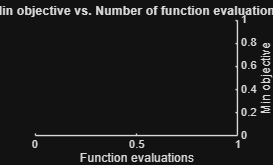


=== Running Training 1 (trainNetwork) ===



=== Done Training 1 ===
accuarcy = 93.8700 %

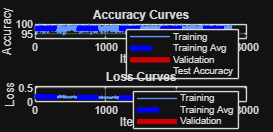

BOresults = bayesopt(objFcn,OptimizationVars, ...
    'MaxObjectiveEvaluations',BONumofItr, ...
    'AcquisitionFunctionName','expected-improvement-plus');

Get best hyperparameters

bestParams = BOresults.XAtMinEstimatedObjective;

LearnRate               = bestParams.lr;
ValidationFrequency     = floor(trainDS.NumObservations/MiniBatchSize);    
RegulizationFactor      = bestParams.l2;

if engine == "trainNetwork" 
    LRdropFrequency     = bestParams.lrdf;
    DropRateFactor      = bestParams.dr; 
    ValidationPatience  = bestParams.vp;
else
    DropRateFactor      = 80;  
    LRdropFrequency     = 0.1;  
    ValidationPatience  = 40;   
end


Retraining the Best points with Random Seeds; may achieve better values 

metricsTest = zeros(RNDSeedsTest, 4);

for CurrentRun = 1:RNDSeedsTest
    expNum = BONumofItr+CurrentRun;             
    rng(CurrentRun, 'twister'); 


    Trainingoptions = createTrainingOptions(Method, LearnRate, DropRateFactor, 3*MaxEpochs, MiniBatchSize, valForOpts, ...
                  floor(trainDS.NumObservations/MiniBatchSize), MomentumFactor, printflag, LRdropFrequency, RegulizationFactor, ValidationPatience, engine, '', 0);
   
    [net,outputFolder,baseFilename] = runfile(trainDS,testDS,testLabels,NetworkLayers,Trainingoptions, ...
                  Method, LayersCount, CurrentRun+BONumofItr, printflag, saveflag, engine, CategoriesArr, TESTFOLDER, '');

    if printflag | saveflag

        figCM = figure('Name',sprintf('Run %d Confusion Matrices', expNum),'NumberTitle','off');
        set(figCM, 'Position', [100 100 3000 1000]);
        subplot(1,3,1);
        [trainev,cmTrain] = evaluateClassification(net,trainLabels,trainDS,outputFolder,baseFilename,1,"training");
        confusionchart(cmTrain);
        title(sprintf('Training CM (Run %d),acc = %.4f %%', CurrentRun,trainev(1)*100));

        subplot(1,3,2);  
        [validnev,cmval] = evaluateClassification(net,valLabels,valDS,outputFolder,baseFilename,1,"validation");
        confusionchart(cmval);
        title(sprintf('Validation CM (Run %d),acc = %.4f %%', CurrentRun,validnev(1)*100));
        
        subplot(1,3,3);  
        [testev,cmtest] = evaluateClassification(net,testLabels,testDS,outputFolder,baseFilename,1,"Testing");
        confusionchart(cmtest);
        title(sprintf('Testing CM (Run %d),acc = %.4f %%', CurrentRun,testev(1)*100));
        
        exportgraphics(figCM, fullfile(outputFolder, sprintf('ConfusionMatrices_Run%d.png',expNum)), 'Resolution', 300);
        if printflag
            close(figCM);
        end
    else
        [testev,~] = evaluateClassification(net,testLabels,testDS,outputFolder,baseFilename,1,"Testing");
    end
    
    metricsTest(CurrentRun, :) = testev(:)' * 100; 
end

Calculating the mean and Standard deviation


meanMetrics = mean(metricsTest, 1);
stdMetrics  = std(metricsTest, 0, 1);
allMetrics = [metricsTest; meanMetrics; stdMetrics];
allMetrics = round(allMetrics, 3);

rowNames = [arrayfun(@(x) sprintf('Run %d', x), 1:RNDSeedsTest, 'UniformOutput', false), ...
            {'Mean', 'Std'}];

resultsTable = array2table(allMetrics, ...
    'VariableNames', {'Accuracy(%)', 'Precision(%)', 'Recall(%)', 'F1-score(%)'}, ...
    'RowNames', rowNames);


if printflag
    fig = uifigure('Position',[100 100 500 75+25*RNDSeedsTest]); % high-res size for printing
    t = uitable(fig, ...
        'Data', allMetrics, ...
        'ColumnName', {'Accuracy(%)', 'Precision(%)', 'Recall(%)', 'F1-score(%)'}, ...
        'RowName', rowNames, ...
        'Units','normalized', ...
        'Position',[0 0 1 1]); % fill entire figure
       
    if saveflag
        resultsImageFile = fullfile(TESTFOLDER, 'ResultsTable.png');
        exportapp(fig, resultsImageFile);  
    end
    
    close(fig);  % free memory
end

function obj = trainAndValidate(x, trainDS, valForOpts, testDS, ...
                trainLabels, valLabels, testLabels, ...
                Method, layers, co, engine, cn, lambda, printflag, saveflag, TESTFOLDER, MaxEpochs,mb,mo)
    persistent expNum
    if isempty(expNum), expNum = 1; else, expNum = expNum + 1; end
    
    vf = floor(numel(trainLabels)/mb);

    if engine == "trainNetwork"
        dr = x.dr;  lrdf = x.lrdf;  vp = x.vp;     
    else
         dr = 80;  lrdf = 0.1;  vp = 40;  
    end

    options = createTrainingOptions(Method, x.lr, dr, MaxEpochs, mb, valForOpts, vf, ...
                  mo, printflag, lrdf, x.l2, vp, engine, '', 0);  
   
    [net,outputfolder,basefilename] = runfile(trainDS,testDS,testLabels,layers,options, ...
                  Method, co, expNum, printflag, saveflag, engine, cn, TESTFOLDER, '');

    [traineva,~] = evaluateClassification(net,trainLabels,trainDS,outputfolder,basefilename,saveflag,"training");
    [valev,~]    = evaluateClassification(net,valLabels,valForOpts,outputfolder,basefilename,saveflag,"validation");

    obj = (1-lambda)*(1 - valev(1))...
        + lambda * max(traineva(1)-valev(1),0);
 end
